# Sesión 3. FUNCIONES EN MATLAB

# 3.1. Cálculo de límites

**Ejemplo.** Calcula el límite de $f\left(x\right)=\frac{x-1}{x^3 -x}$ cuando x=-1

syms x; f(x)=exp(1/x)

$$f(x) = {\mathrm{e}}^{1/x}$$

limite_izquierda=limit(f(x),x,-1,'left')

$$limite\_izquierda = {\mathrm{e}}^{-1}$$

limite_derecha=limit(f(x),x,-1,'right')

$$limite\_derecha = {\mathrm{e}}^{-1}$$

limite_derecha=limit(f(x),x,-1)

$$limite\_derecha = {\mathrm{e}}^{-1}$$

Por tanto, el límite de la función en $x=-1$ no existe.

**Ejercicio 1.** Calcula:

a)$\lim_{x\longrightarrow \infty } \frac{x^3 +5x+3}{x^2 +1}$    

b)$\lim_{x\longrightarrow \infty } \frac{{2x}^3 +5x+3}{{5x}^3 +1}\;\;\;$

c)$\lim_{x\longrightarrow \infty } \frac{x^3 +5x+3}{x^4 +1}$

syms x; f(x)=(x^3+5*x+3)/(x^2+1)

$$f(x) = \frac{x^{3}+5\,x+3}{x^{2}+1}$$

limit (f(x),x,inf)

$$ans = \infty$$

syms x; f(x)=(2*x^3+5*x+3)/(5*x^3+1)

$$f(x) = \frac{2\,x^{3}+5\,x+3}{5\,x^{3}+1}$$

limit (f(x),x,inf)

$$ans = \frac{2}{5}$$

syms x; f(x)=(x^3+5*x+3)/(x^4+1)

$$f(x) = \frac{x^{3}+5\,x+3}{x^{4}+1}$$

limit (f(x),x,inf)

$$ans = 0$$

**Ejercicio 2**. Calcula$\lim_{x\longrightarrow 0^- } e^{\frac{1}{x}}$   y $\lim_{x\longrightarrow 0^+ } e^{\frac{1}{x}}$.

syms x; f(x) = (exp(1/x))

$$f(x) = {\mathrm{e}}^{1/x}$$

limit (f(x),x,0,'left')

$$ans = 0$$

limit (f(x),x,0,'right')

$$ans = \infty$$

¿Qué puedes decir sobre el límite de la función en x=0?

**Ejercicio 3.** Calcula los siguientes límites:


$$\lim_{x\longrightarrow 1} \frac{x^3 -1}{x^2 +4x+5}$$
      
$$\lim_{x\longrightarrow 0^+ } \frac{5x}{1-e^{\frac{1}{x}} }$$
       
$$\lim_{x\longrightarrow 0} \frac{e^{\frac{1}{x}} }{1+e^{\frac{1}{x}} }$$
       
$$\lim_{x\longrightarrow 2^- } \sin \left(x^3 +5x-1\right)$$
   

syms x; f(x)=(x^3-1)/(x^2+4*x+5)

$$f(x) = \frac{x^{3}-1}{x^{2}+4\,x+5}$$

limit (f(x),x,1)

$$ans = 0$$

syms x; f(x)=(5*x)/(1-exp(1/x))

$$f(x) = -\frac{5\,x}{{\mathrm{e}}^{1/x}-1}$$

limit (f(x),x,0,'right')

$$ans = 0$$

syms x; f(x)=(exp(1/x))/(1+exp(1/x))

$$f(x) = \frac{{\mathrm{e}}^{1/x}}{{\mathrm{e}}^{1/x}+1}$$

limit (f(x),x,0)

$$ans = \mathrm{NaN}$$

syms x; f(x)=sin(x^3+5*x-1)

$$f(x) = \sin\left(x^{3}+5\,x-1\right)$$

limit (f(x),x,2,'left')

$$ans = \sin\left(17\right)$$

# 3.2. Representación de funciones

Usaremos las siguientes instrucciones en Matlab:

- Opción 1: de forma numérica

o bien

- Opción 2: utilizando funciones simbólicas

**Ejemplo.** Representa la función $f\left(x\right)=\cos \left(x\right)$ en el intervalo $\left\lbrack \frac{-3\pi }{2},\frac{3\pi }{2}\right\rbrack$.

- Opción 1, construyendo vectores numéricos: `plot`

Vamos a tomar 40 puntos de $x$ en el intervalo:

x=linspace(-3*pi/2,3*pi/2,40);

A continuación definimos la función y la representamos:

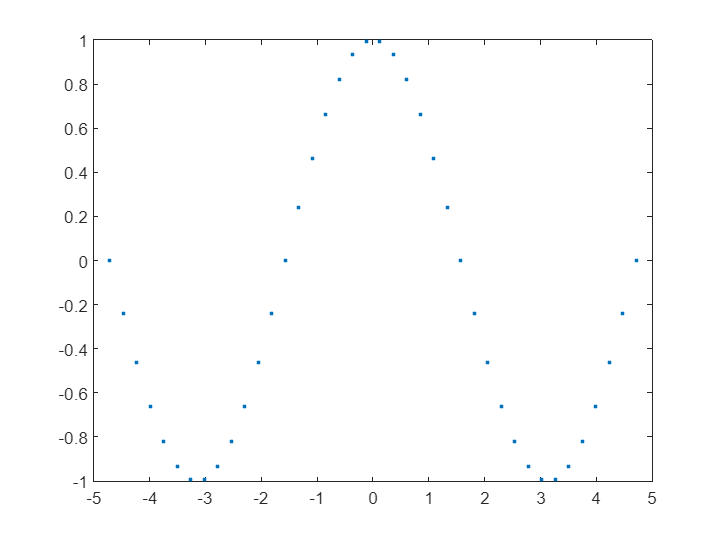

y=cos(x);
plot(x,y,'.')

- Opción 2, definiendo variable simbólica: `fplot`

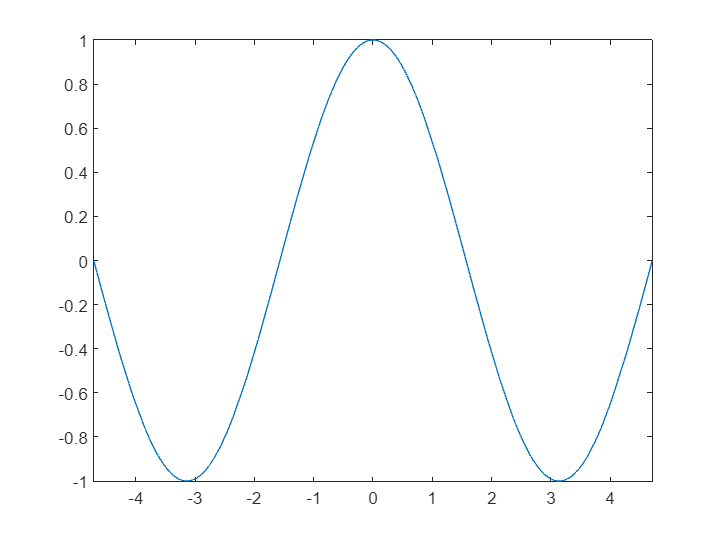

syms x
f(x)=cos(x); 
fplot(f(x),[-3*pi/2,3*pi/2])

**Ejercicio 4. **Representa la función $f\left(x\right)=x^3 +2x^2 +5x+3$ tomando 100 puntos de $x$ en el intervalo $\left\lbrack -5,5\right\rbrack$.

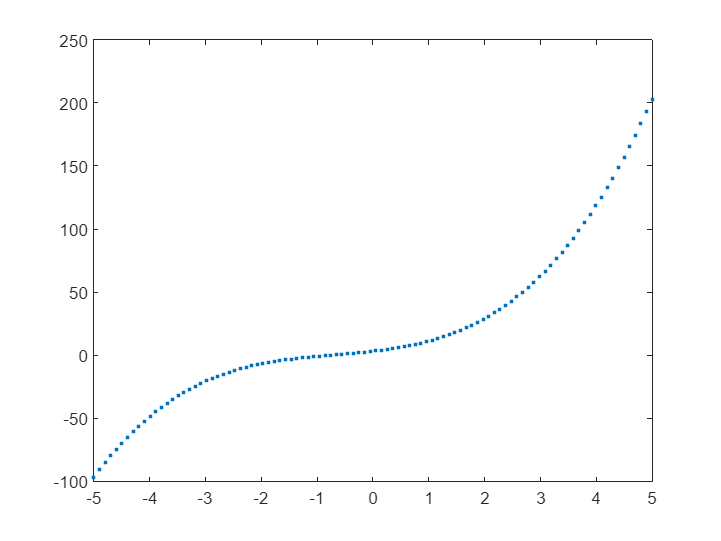

x=linspace(-5,5,100);
y=x.^3+2*x.^2+5*x+3;
plot(x,y,'.')

# 3.3. Gráficas de funciones definidas a trozos

Para las funciones definidas a trozos usaremos las instrucciones de Matlab `if` y `for:`

**Ejemplo. **Representar la función $f\left(x\right)=\left\lbrace \begin{array}{ll}
x^3 +2x-2 & -1\le x\le 3\\
x^2 -3x+2 & \;\;\;3<x\le 5
\end{array}\right.$ .

Vamos a hacerlo en primer lugar utilizando funciones simbólicas:

syms x
f1(x)=x^3+2*x-2

$$f1(x) = x^{3}+2\,x-2$$

 f2(x)=x^2-3*x+2

$$f2(x) = x^{2}-3\,x+2$$

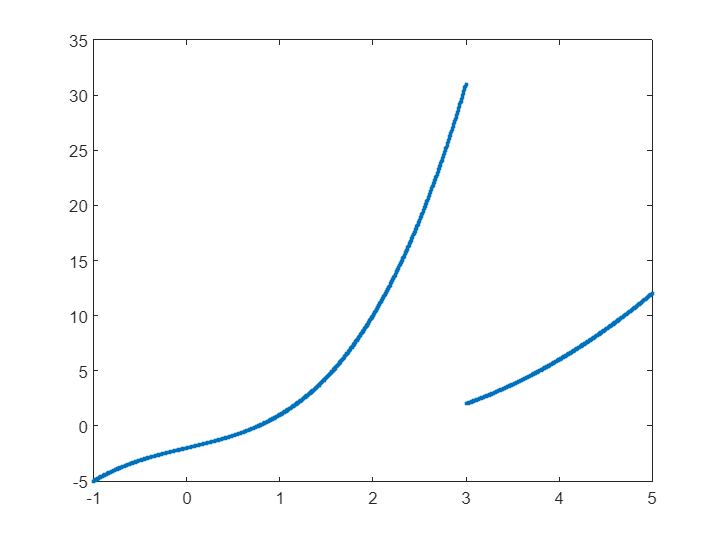

x=linspace(-1,5,1000);
for i=1:1000
    if (-1<=x(i) & x(i)<=3) y(i)=f1(x(i));
    elseif (x(i)>3 & x(i)<=5) y(i)=f2(x(i));   
    end
end
plot(x,y,'.')

Ahora haremos lo mismo pero utilizando variables numéricas:

x=linspace(-1,5,1000);
for i=1:1000
 
       if (-1<=x(i) & x(i)<=3) y(i)=x(i)^3+2*x(i)-2;
   elseif (x(i)>3 & x(i)<=5) y(i)=x(i)^2-3*x(i)+2;
   
    end
end
plot(x,y,'.')

**Ejercicio 5.** Consideremos la función $f\left(x\right)=\frac{\left|x\right|}{\sin \left(x\right)}$. 

a) Representa gráficamente la función $f(x)$ tomando 50 puntos de $x$ en el intervalo $[-2,2]$. 

b) Calcula el límite de la función en el punto $x=0$.

c) ¿Qué crees que sucede en puntos próximos a $x=0$?

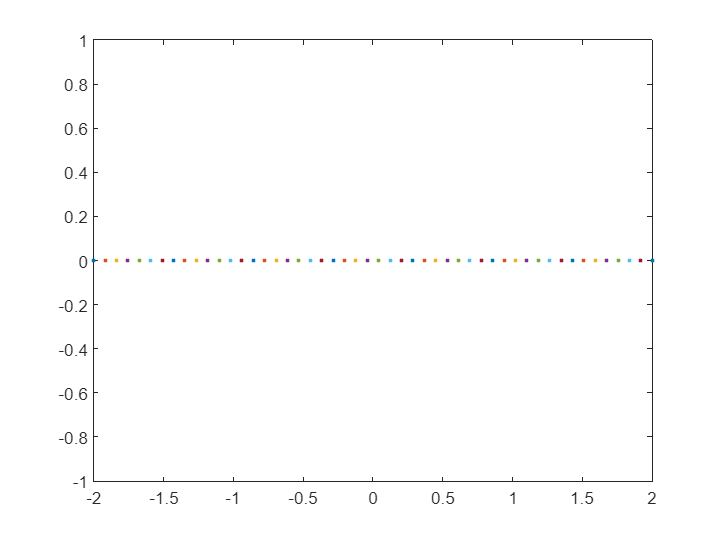

x=linspace(-2,2,50);
y=(abs(x))/(sin(x));
plot(x,y,'.')

syms x; f(x)=(abs(x))/(sin(x))

$$f(x) = \frac{\left|x\right|}{\sin\left(x\right)}$$

limit(f(x),x,0)

$$ans = \mathrm{NaN}$$

**Ejercicio 6.** Representa la gráfica de las siguientes funciones utilizando `plot` y utilizando `fplot`:

a)$f\left(x\right)=\frac{\sin \left(2x\right)}{x}$      

b) $f\left(x\right)=\left\lbrace \begin{array}{ll}
e^{-x}  & -1\le x\le 0\\
x^2 -3x+2 & \;\;\;0<x\le 5
\end{array}\right.$    

c)$f\left(x\right)=\left\lbrace \;\begin{array}{ll}
\frac{\sin \left(2x\right)}{x} & \textrm{si}\;x\not= 0\\
\;\;\;\;\;2 & \;\textrm{si}\;x=0
\end{array}\right.$

syms x; f(x)=(sin(2*x))/(x)

$$f(x) = \frac{\sin\left(2\,x\right)}{x}$$

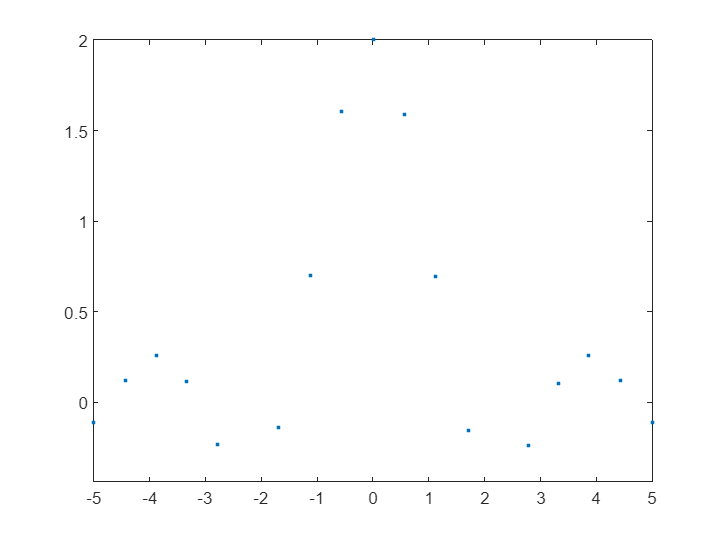

fplot(f(x),'.')

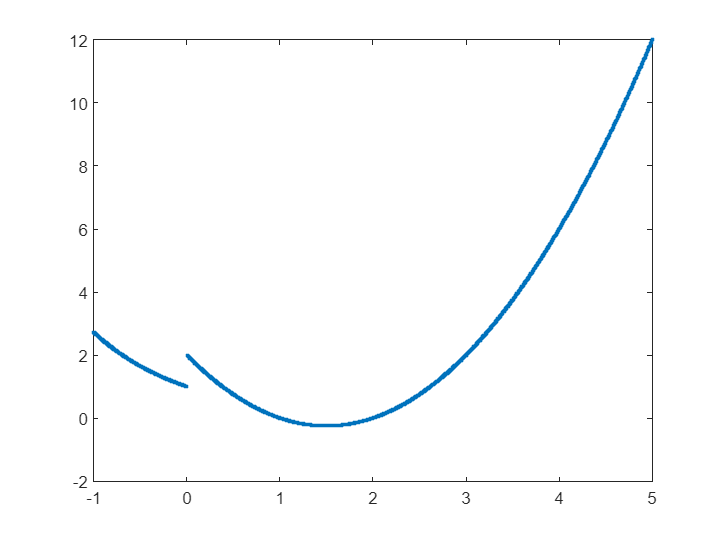

syms x;
f1(x)=exp(-x);
f2(x)=x^2-3*x+2;
x=linspace(-1,5,1000);
for i=1:1000
    if (-1<=x(i) & x(i)<=0)
        y(i)=f1(x(i));
    elseif (0<x(i) & x(i)<=5)
        y(i)=f2(x(i));
    end
end
plot(x,y,'.')

syms x;
f1(x)=(sin(2*x))/(x);
f2(x)=2;
x=linspace(-1,5,1000)

x =    -1.0000   -0.9940   -0.9880   -0.9820   -0.9760   -0.9700   -0.9640   -0.9580   -0.9520   -0.9459   -0.9399   -0.9339   -0.9279   -0.9219   -0.9159   -0.9099   -0.9039   -0.8979   -0.8919   -0.8859   -0.8799   -0.8739   -0.8679   -0.8619   -0.8559   -0.8498   -0.8438   -0.8378   -0.8318   -0.8258   -0.8198   -0.8138   -0.8078   -0.8018   -0.7958   -0.7898   -0.7838   -0.7778   -0.7718   -0.7658   -0.7598   -0.7538   -0.7477   -0.7417   -0.7357   -0.7297   -0.7237   -0.7177   -0.7117   -0.7057


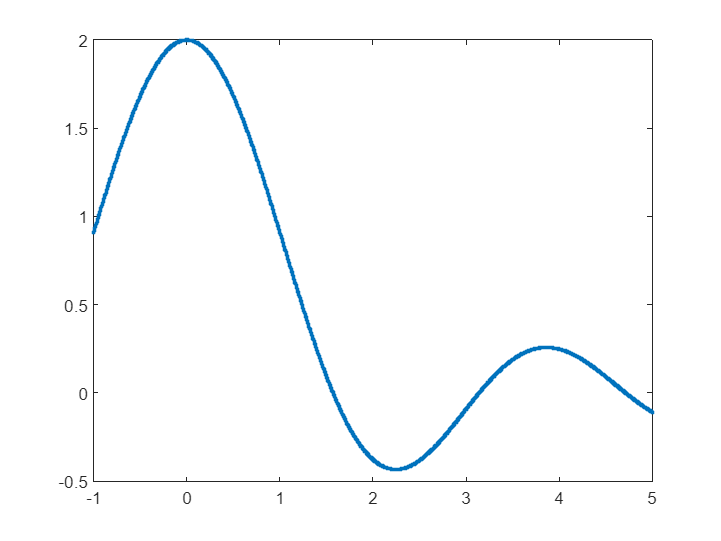

for i=1:1000
    if (x(i)~=0)
        y(i)=f1(x(i));
    elseif (x(i)==0)
        y(i)=f2(x(i));   
    end
end
plot(x,y,'.')

**Ejercicio 7.** Representa las siguientes funciones y estudia su límite en el punto $x=1$:

a) $f\left(x\right)=\left\lbrace \begin{array}{ll}
x^3 +5x-2 & -1\le x\le 1\\
x^2 -2x+1 & \;\;\;1<x\le 5
\end{array}\right.$    

b) $g\left(x\right)=\left\lbrace \begin{array}{ll}
e^x  & x\le 1\\
\sin \left(x^2 \right) & \;x>1
\end{array}\right.$ 

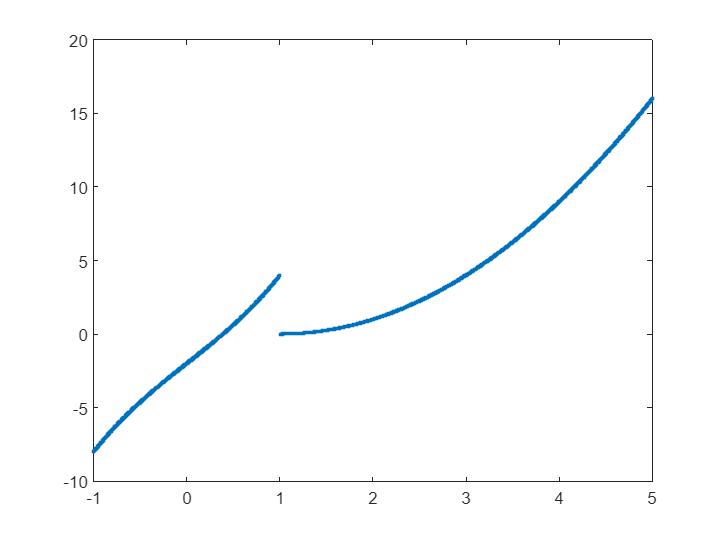

syms x;
f1(x)=x^3+5*x-2;
f2(x)=x^2-2*x+1;
x=linspace(-1,5,1000);
for i=1:1000
    if (-1<=x(i) & x(i)<=1)
        y(i)=f1(x(i));
    elseif (1<x(i) & x(i)<=5)
        y(i)=f2(x(i));
    end
end
plot(x,y,'.')

syms x;
limit(f1(x),x,1)

$$ans = 4$$